% === Configuração do ROS ===
clc; clear all; close all;
setenv('ROS_MASTER_URI','http://192.168.245.132:11311');
setenv('ROS_IP','192.168.245.1');
rosshutdown;

Shutting down global node /matlab_global_node_18985 with NodeURI http://192.168.245.1:49942/ and MasterURI http://192.168.245.132:11311.


rosinit('192.168.245.132', 11311);

The value of the ROS_IP environment variable, 192.168.245.1, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_55088 with NodeURI http://192.168.245.1:51824/ and MasterURI http://192.168.245.132:11311.



%cliente Traj
[trajAct,trajGoal] = rosactionclient('/pos_joint_traj_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory','DataFormat','struct');
trajAct.FeedbackFcn = []; 
trajAct.ResultFcn = [];

%Cliente Garra
[gripAct, gripGoal] = rosactionclient('/gripper_controller/follow_joint_trajectory', 'control_msgs/FollowJointTrajectory', 'DataFormat', 'struct');
gripAct.FeedbackFcn = [];
gripAct.ResultFcn = [];
waitForServer(gripAct);

mover_para([0 0 0 0 0 0], trajGoal, trajAct)

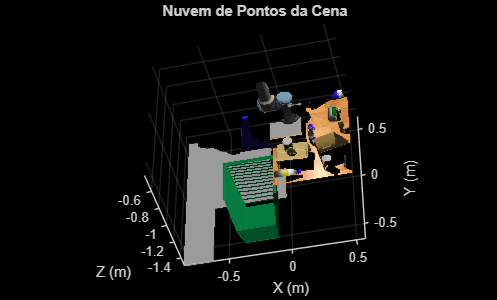

% === Captura da nuvem de pontos do sensor ===
pcSub = rossubscriber('/camera/depth/points', 'sensor_msgs/PointCloud2', 'DataFormat', 'struct');
pause(1);
pcMsg = receive(pcSub, 3);

% Extrai XYZ
xyz = rosReadXYZ(pcMsg, "PreserveStructureOnRead", true);
xyzVec = reshape(xyz, [], 3);

% Extrai RGB (opcional)
try
    rgb = rosReadRGB(pcMsg, "PreserveStructureOnRead", true);
    rgbVec = reshape(rgb, [], 3);
    hasColor = true;
catch
    hasColor = false;
end

% Remove NaNs
valid = ~any(isnan(xyzVec), 2);
xyzClean = xyzVec(valid, :);
xyzClean(:,3) = -xyzClean(:,3);  % Inverte o eixo Z para alinhar com câmera

% Cria ptCloud da cena
if hasColor
    rgbClean = uint8(255 * rgbVec(valid, :));
    ptCena = pointCloud(xyzClean, "Color", rgbClean);
else
    ptCena = pointCloud(xyzClean);
end

% Mostrar cena
figure;
pcshow(ptCena, VerticalAxis="Y", VerticalAxisDir="Up");
title("Nuvem de Pontos da Cena");
xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");

% === Após criar ou unir a nuvem de pontos ===
% Define o diretório e nome de arquivo
outputFolder = "C:\Users\pecci\OneDrive\Desktop\Nuvem de pontos";       % ajustar conforme desejar
if ~isfolder(outputFolder)
    mkdir(outputFolder);
end
timestamp = datestr(now, "yyyymmdd_HHMMSS");
fileName = fullfile(outputFolder, "nuvemCena_" + timestamp + ".ply");

% Converte para single se for necessário (PCD com cores):
%ptCena = pointCloud(single(ptCena.Location), "Color", ptCena.Color);

% Salva usando pcwrite
pcwrite(ptCena, fileName, "Encoding", "binary");  % salva em formato binário :contentReference[oaicite:1]{index=1}

disp("Nuvem de pontos salva em: " + fileName);

Nuvem de pontos salva em: C:\Users\pecci\OneDrive\Desktop\Nuvem de pontos\nuvemCena_20250622_205038.ply
